# Compare Separation and Experiment Tube Test Data - Events 

#### Exp - continuous event mining 

% Remove contamination and transform data 
load('exp_tube_con.mat')
em=rem_dup_em(em);
[N,nm]=size(em{1,1}.eve);

Find events with 4 specified lengths: 5s, 20s, 40s, 100s 

klist={5,20,40,100};% find events separately for each k
ev_merge=cell(N,nm);
% events
for p=1:N
    for m=1:nm
        for r=1:2 % two rounds
            [allt,allm,allk]=alltmk(klist,em{r,1}.K{p,m},em{r,1}.M{p,m},em{r,1}.time{p,m});
            em{r,1}.allt{p,m}=allt;em{r,1}.allm{p,m}=allm;em{r,1}.klist=klist;em{r,1}.allk{p,m}=allk;
        end
        ev_merge{p,m}=cell(1,4);
        for k=1:4
            % merge events from the two rounds of detection
            ev_merge{p,m}{k}=combine_2_r(em{1,1}.allt{p,m}{k},find(em{2,1}.timefilter{p,m}),em{2,1}.allt{p,m}{k},'position','center',"k",klist{k});
            ev_merge{p,m}{k}=remove_time_ovp(ev_merge{p,m}{k},klist{k}); % remove highly overlapped events
        end
    end
end

#### Same for separation data -

% Remove contamination and transform data 
load('sep_tube_con.mat')
em_sep=rem_dup_em(em_sep);
[N,nm]=size(em_sep{1,1}.eve);

Find events with 4 specified lengths: 5s, 20s, 40s, 100s 

klist={5,20,40,100};% find events separately for each k
ev_merge_sep=cell(N,nm);
% events
for p=1:N
    for m=1:nm
        for r=1:2 % two rounds
            [allt,allm,allk]=alltmk(klist,em_sep{r,1}.K{p,m},em_sep{r,1}.M{p,m},em_sep{r,1}.time{p,m});
            em_sep{r,1}.allt{p,m}=allt;em_sep{r,1}.allm{p,m}=allm;em_sep{r,1}.klist=klist;em_sep{r,1}.allk{p,m}=allk;
        end
        ev_merge_sep{p,m}=cell(1,4);
        for k=1:4
            % merge events from the two rounds of detection
            ev_merge_sep{p,m}{k}=combine_2_r(em_sep{1,1}.allt{p,m}{k},find(em_sep{2,1}.timefilter{p,m}),em_sep{2,1}.allt{p,m}{k},'position','center',"k",klist{k});
            ev_merge_sep{p,m}{k}=remove_time_ovp(ev_merge_sep{p,m}{k},klist{k}); % remove highly overlapped events
        end
    end
end

Plot experiment data 

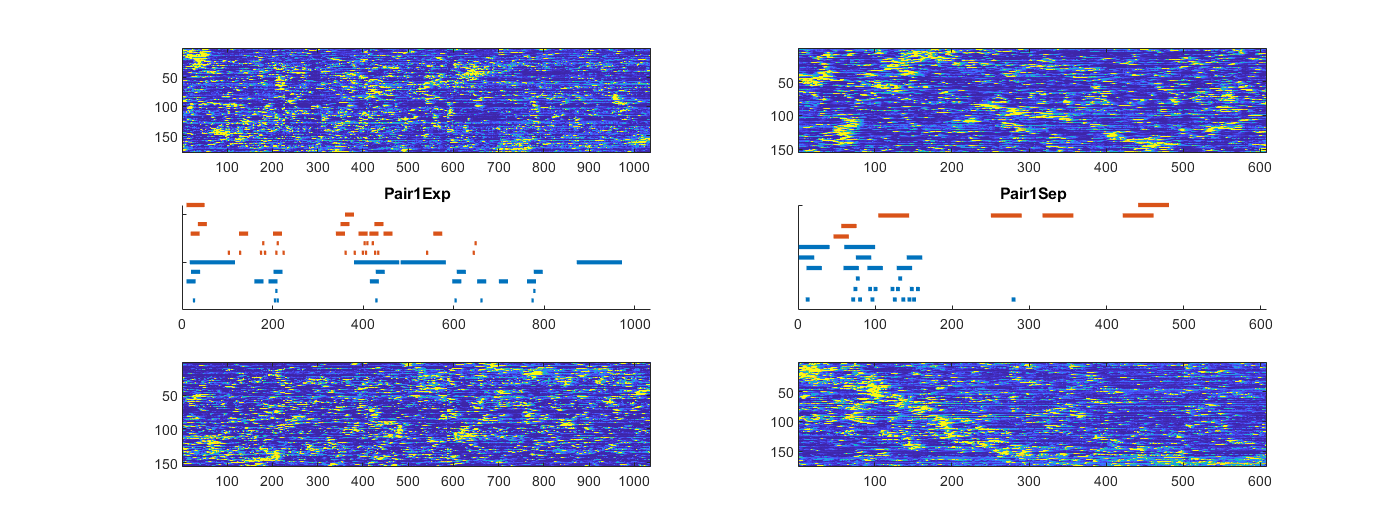

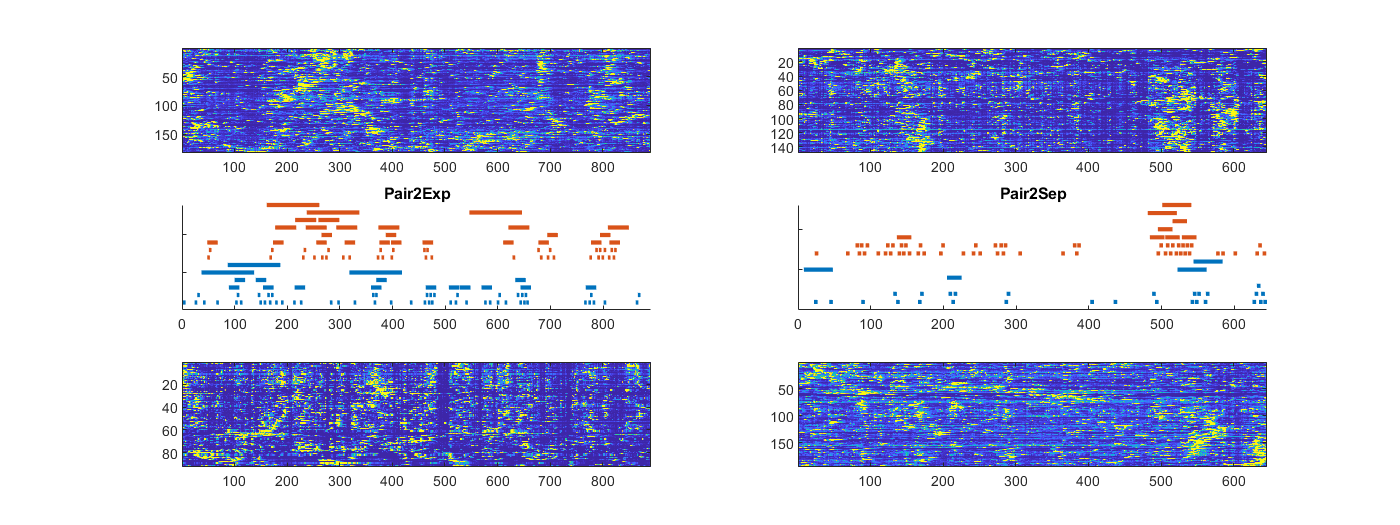

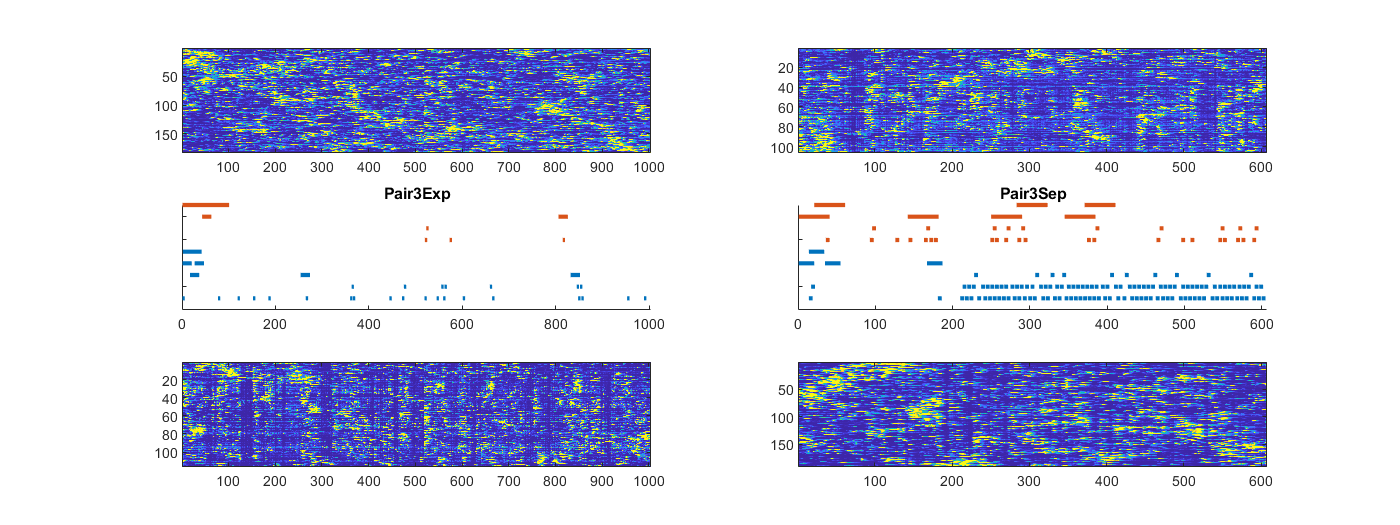

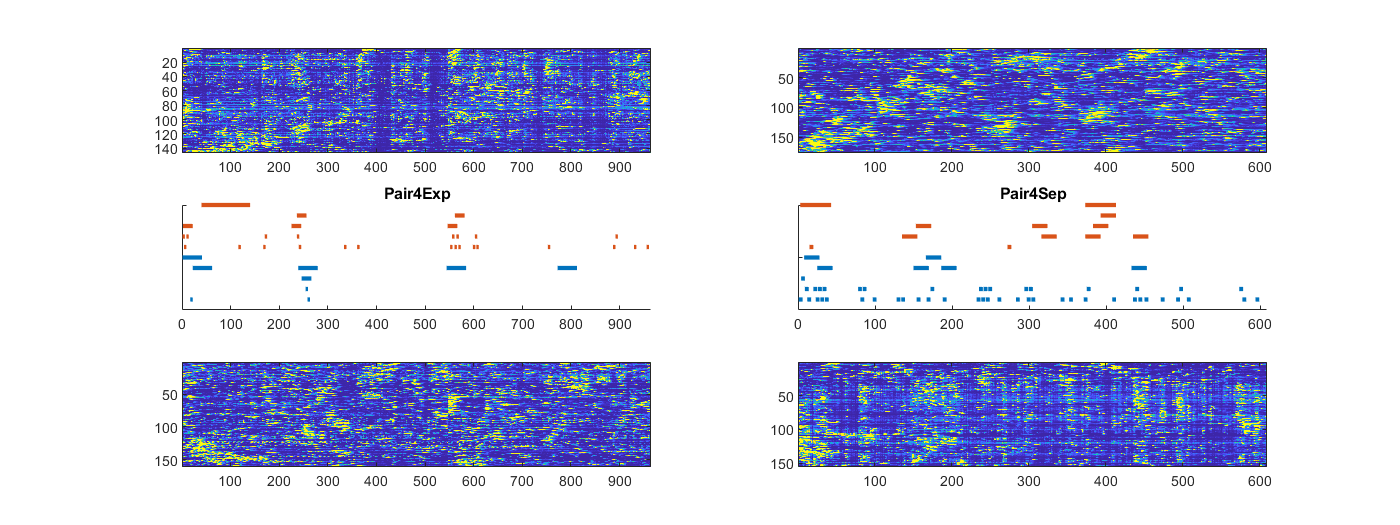

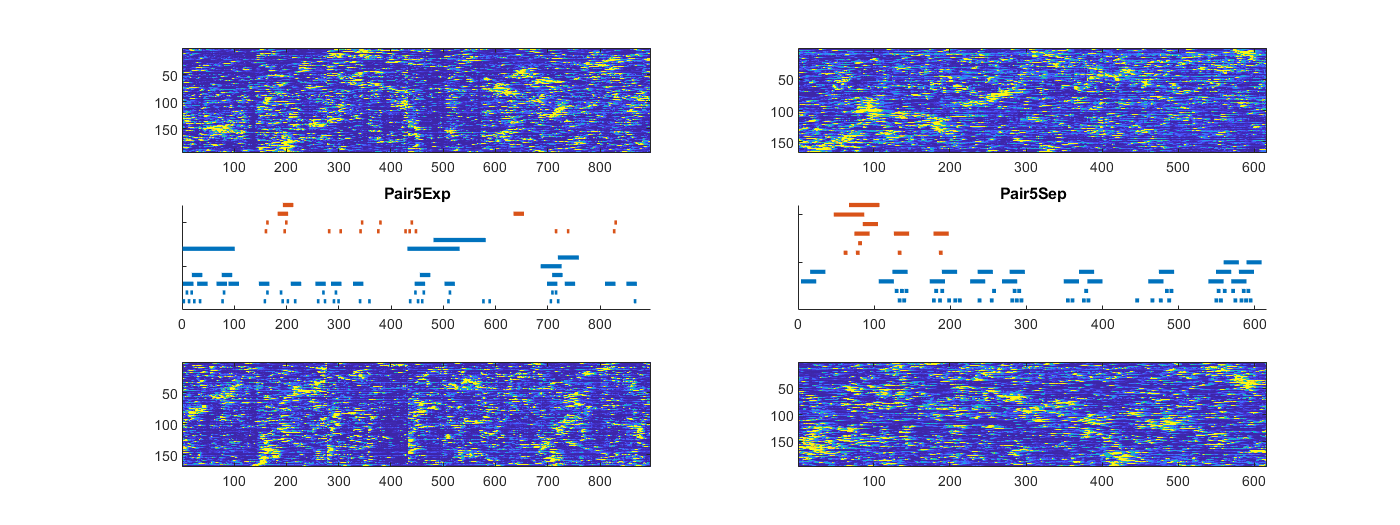

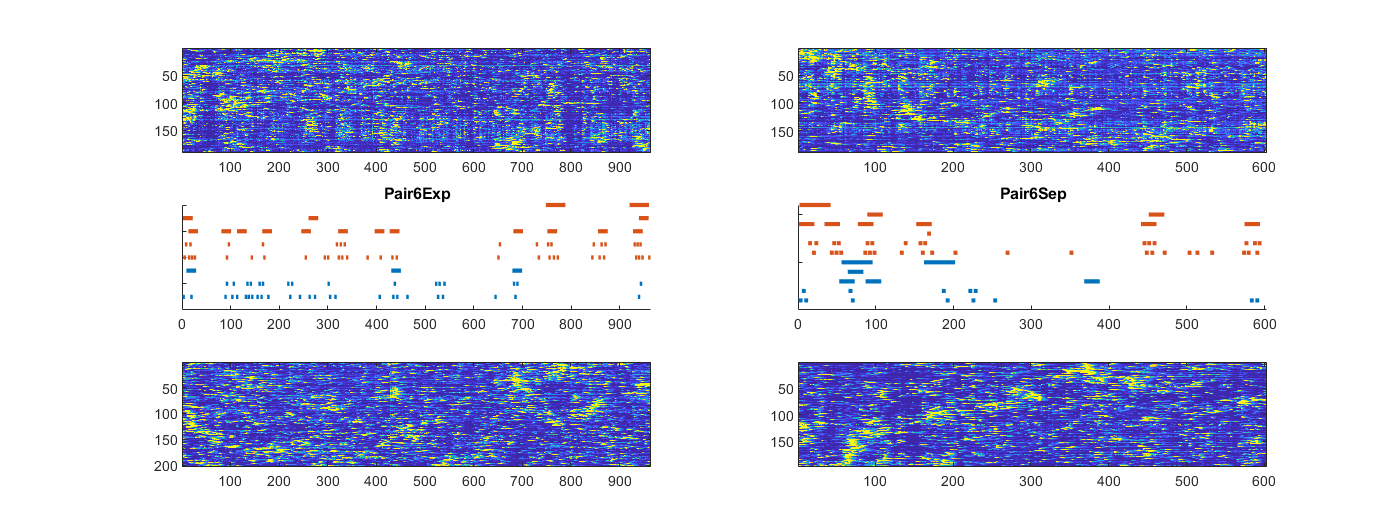

for p=1:N
f=figure;
f.Position(3)=2*f.Position(3);
subplot(3,2,1)
plot_raster(em{1,1}.ca_cl{p,2},'bin',false);
subplot(3,2,3)
new_eve_plot_arena(ev_merge{p,1},ev_merge{p,2},klist,size(em{1,1}.ca_cl{p,1},2));
title(sprintf('Pair%dExp',p))
subplot(3,2,5)
plot_raster(em{1,1}.ca_cl{p,1},"bin",false);
subplot(3,2,2)
plot_raster(em_sep{1,1}.ca_cl{p,2},'bin',false);
subplot(3,2,4)
new_eve_plot_arena(ev_merge_sep{p,1},ev_merge_sep{p,2},klist,size(em_sep{1,1}.ca_cl{p,1},2));
title(sprintf('Pair%dSep',p))
subplot(3,2,6)
plot_raster(em_sep{1,1}.ca_cl{p,1},"bin",false);
end

#### Compare number of events of the first 600s 

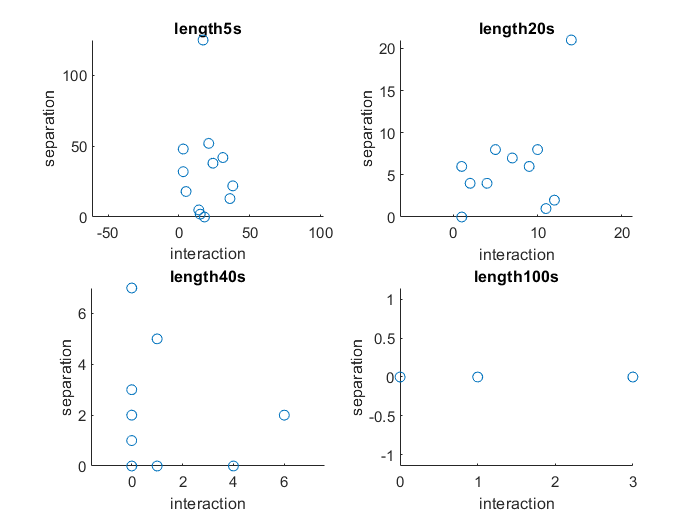

close all
n=0;l=600;
for p=1:N
    for m=1:2
        n=n+1;
        for k=1:4
            neve(k,1,n)=sum(ev_merge{p,m}{k}<l);
            neve(k,2,n)=sum(ev_merge_sep{p,m}{k}<l);
        end
    end
end
% err1=nanste(neve,3);
% hBar=bar(squeeze(mean(neve,3)));
% for k1 = 1:size(neve,2)
%     x(:,k1) = bsxfun(@plus, hBar(1).XData, hBar(k1).XOffset');    % Note: eXOffsete Is An Undocumented Feature; This Selects The xbarp Centres
%     y(:,k1) = hBar(k1).YData;                                     % Individual Bar Heights
% end
% hold on
% errorbar(x,y, err1, '.k')                                      % Plot Error Bars
% hold off
% legend(hBar,{'exp','sep'});xticklabels({'5s','20s','40s','100s'})
% scatter of n events 
for k=1:4
    subplot(2,2,k)
    scatter(squeeze(neve(k,1,:)),squeeze(neve(k,2,:))); axis equal
    title(sprintf('length%ds',klist{k}));xlabel('interaction');ylabel('separation')
end